# Periodogram-based OFDM Radar with DFT-spread Single Target

modOrder = 16; % modulation order being used
modType = "QAM"; % type of modulation being used
c = 3e8; % The speed of light

subcarrierSpacing = 78.125e3; % subcarrier spacing for 802.11g
Tu = 1/subcarrierSpacing; % the "useful" symbol period
G = 1/8; % the guard interval fraction
Tg = G*Tu; % the guard interval time
To = Tu + Tg; % the OFDM symbol duration (period)
fC = 5.9e9; % 802.11a uses the 2.4 GHz band
N = 52; % 48 for data, and 4 pilot tones
numPilotTones = 4; % no. pilot tones used

signalSet = qammod((0:modOrder-1), modOrder, 'UnitAveragePower', true);

% Target parameters:
Vrel = 20; % The relative velocity of our target to the transmitter
d = 50; % The distance between the target and the transmitter
targetRCS = 10; % The radar cross section of the target
targetPhi = 2*pi*rand; % The random phase offset caused by the target

% Working out the approximate Doppler shift caused when the EM wave impinges on the
% target:
fD = 2*fC*(Vrel/c);

% And the time delay:
timeDelay = 2*d/c;

M = 64; % the no. of symbols in a frame
mapType = "interleave"; % type of mapping that is taking place
K = 4;
L = K*N; % size of IFFT block used on Tx side

Ftx = zeros(N, M); % the transmit frame, 52x64

% loading the transmit frame with symbols from the signal set (1x16)
for row = 1:N %each row with M(64) symbols
    Ftx(row, :) = randsample(signalSet, M, true);
end

FtxCopy = Ftx; % making a copy before we apply FFT to Ftx
Ftx = fft(Ftx); % taking the FFT before performing the symbol mapping stage

% Now we need to map the o/p of DFT block to the i/p of IDFT block:
excess = (L/2-1) - N; % the no. of excess i/p pins on IDFT block
symbolMapOp = zeros(L, M); % output of symbol mapper - this goes into IDFT

switch (mapType)
    case "interleave"
        % The variable below is the amount of zeros that we will insert between
        % each symbol on the input pins of the IDFT block:
        interPadLength = floor(excess/(N-1));
        % Below we are mapping each of the (N) outputs of the DFT block to
        % the (L) inputs of the IDFT block
        for i = 1:N
            symbolMapOp(1+1+(i-1)*(interPadLength+1), :) = Ftx(i, :);
        end
    case "local"
        % insertIndex is the index where the first symbol from the output
        % of the Tx-side DFT block should be mapped to in the Tx-side IDFT
        % block. In "localised" mapping, the data (Ftx in our case) is 
        % usually padded above and below by zeros:
        insertIndex = (excess + 1)/2 + 1 + 1;
        symbolMapOp(insertIndex:insertIndex+N-1, :) = Ftx;
    otherwise
        disp("ERROR: check the value of 'mapType' at the top of the script.")
        return
end

% Index vectors: l is for the columns, k is for the rows
l = 0:M-1;
k = 0:(L-1);

% The attenuation factor, b:
%b = sqrt((c*targetRCS)/((4*pi)^3*(d^4)*(fC^2)));
b = 6e-3;

Frx = zeros(L, M); % The received frame (currently empty)
Z = wgn(L, M, -40, 'complex'); % Complex Gaussian White noise matrix...

% Next, we form the receive frame by modelling the effect of the channel
% and the target on the transmited frame:
for row = 1:L
    for column = 1:M
        Frx(row, column) = b*symbolMapOp(row, column)*exp(1i*2*pi*(column - 1)*To*fD)*exp(-1i*2*pi*(row - 1)*timeDelay*subcarrierSpacing) + Z(row, column);
    end
end

% The OFDM beacon knows what frame was sent, and hence we can divide the
% received frame by the transmitted one:
F = Frx./symbolMapOp;

% And now we can remove the rows with "Inf" values, which were caused
% by dividing by "0"s in the transmit frame (Ftx)
F(1, :) = 0;
F(L/2 + 1, :) = 0;
F(isinf(F)) = 0;

% The size of the extended periodogram:
Nper = 4*L;
Mper = 4*M;

% The subcarrier spacing should be at least one order of magnitude
% bigger than the largest occurring Doppler shift - hence a value of 1/10 
% for the quantity D...
D = 1/10;

% Defining our search range below:
Nmax = G*Nper; % The row at beyond which we should stop looking for peaks
Mmax = round(D*Mper); % The column beyond which we should stop searching for peaks

% Complex periodogram calculation:
Cper = F; % The complex periodogram is calculated using F...

% Method 1 to calculate the complex periodogram:
Cper = Cper.';
Cper = fft(Cper, Mper); % FFT of each row (length of FFT is Mper)
Cper = Cper.';
Cper = ifft(Cper, Nper); % IFFT of each column...
numCols = size(Cper, 2);
Cper = Cper(1:Nmax, :); % cropping
Cper = flip(fftshift(Cper, 2), 1);
Cper = Cper(:, (numCols/2)-Mmax:(numCols/2)+Mmax-1); % cropping

% Periodogram calculation:
Per = 1/(Nmax*(2*Mmax + 1))*(abs(Cper).^2);

% Getting the maximum value from the cropped periodogram:
maxPer = max(Per(:));

% The x and y axis are reversed in the periodogram...
[y, x] = ind2sub(size(Per), find(Per == maxPer));

% The position indexes. I'm using 'hat' in the variable name as these are
% estimates...
m_hat = x - (size(Per, 2)/2 + 1);
n_hat = size(Per, 1) - y + 1;

tau_hat = (n_hat - 1)/(Nper*subcarrierSpacing); % The time delay...

distance = (n_hat - 1)*c/(2*subcarrierSpacing*Nper);
velocity = (m_hat - 1)*c/(2*fC*To*Mper);

% The index vectors below can be used to find the distance
% and velocity values, which can be used to label the axes...
mIndexes = (1:size(Per, 2)) - (size(Per, 2)/2 + 1);
nIdexes = (1:size(Per, 1));

% Working out the corresponding distance and velocity vector
% associated with each (n, m) index...
distancesVec = (nIdexes - 1)*c/(2*subcarrierSpacing*Nper);
velocitiesVec = round((mIndexes - 1)*c/(2*fC*To*Mper));

% Creating label variables to use with the heatmap object below:
distanceLabels = string(distancesVec);
distanceLabels(~(ceil(distancesVec) == floor(distancesVec))) = "";
velocityLabels = string(velocitiesVec);
%velocityLabels(~(mod(velocitiesVec, 10) == 0)) = "";

h = heatmap(velocitiesVec, flip(distancesVec), Per, 'Colormap', jet(200));
%title("\fontsize{14}\fontname{Georgia}Periodogram-based Target Estimation (" + IEEEstandard + ", \itv\rm\bf_{t} = " + Vrel + ", d_{t} = " + d + ", L = " + L + ", M = " + M + ")");
xlabel('\fontname{Georgia}\bf\itv\rm\bf_{rel.} (m/s)');
ylabel('\fontname{Georgia}\bfDistance (m)');
s = struct(h);

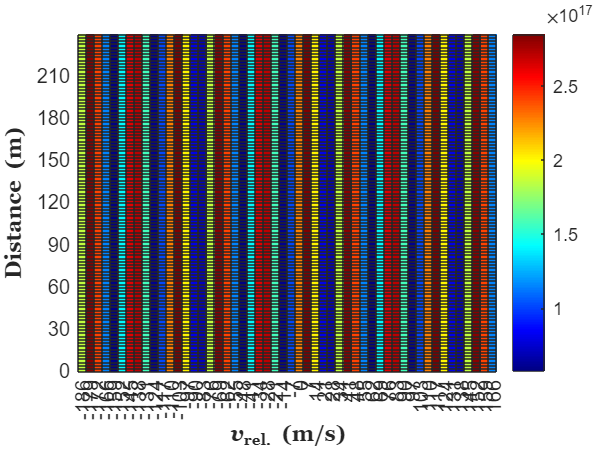

s.XAxis.TickLabelRotation = 90;
h.YDisplayLabels = flip(distanceLabels);
h.XDisplayLabels = velocityLabels;